clearvars
%{
Parent Code:
Research Exploration Maxine 6 oct
Interpolation_20211006_v2
%}

format long

# Task 1 prep

## Data Exploration and Practice Interpolation of BD+55_441

opts = detectImportOptions("BD+55_441.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
preview("BD+55_441.txt",opts)

ans = 8×6 table
      B_time        B_flux       R_time        R_flux       V_time        V_flux 
    ___________    ________    ___________    ________    ___________    ________

     58732.6843    3.497996    58732.68459     1.96183    58732.68445    2.352058
     58732.6843    3.497996    58732.68504    1.942857     58732.6849    2.360458
    58732.68475    3.487289    58732.68549    1.947021    58732.68535    2.329957
     58732.6852    3.450942    58732.68594    1.930594     58732.6858    2.344889
    58732.68565    3.497567    58732.68639    1.942537    58732.68625    2.361048
     58732.6861    3.461555    58732.68684    1.935141    58732.68669    2.333341
    58732.68655    3.431248    58732.68729     1.93129    58732.68714    2.331904
      58732.687    3.455091    58732.6877

BD55_441 = readmatrix("BD+55_441.txt",opts);
whos BD55_441

  Name            Size            Bytes  Class     Attributes

  BD55_441      101x6              4848  double              






%--B_flux--------------------
%{
plot(BD55_441(:,1),BD55_441(:,2),'*')
title('Flux vs time for BD+55\_441 B filter');
xlabel('time');
ylabel('flux');
%}

%{
r = abs([0; BD55_441(:,1)] - [BD55_441(:,1);0])
round(mean(r(3:end-1)),8)
round(std(r(3:end-1)),8)
%}


disp('B Filter')

B Filter


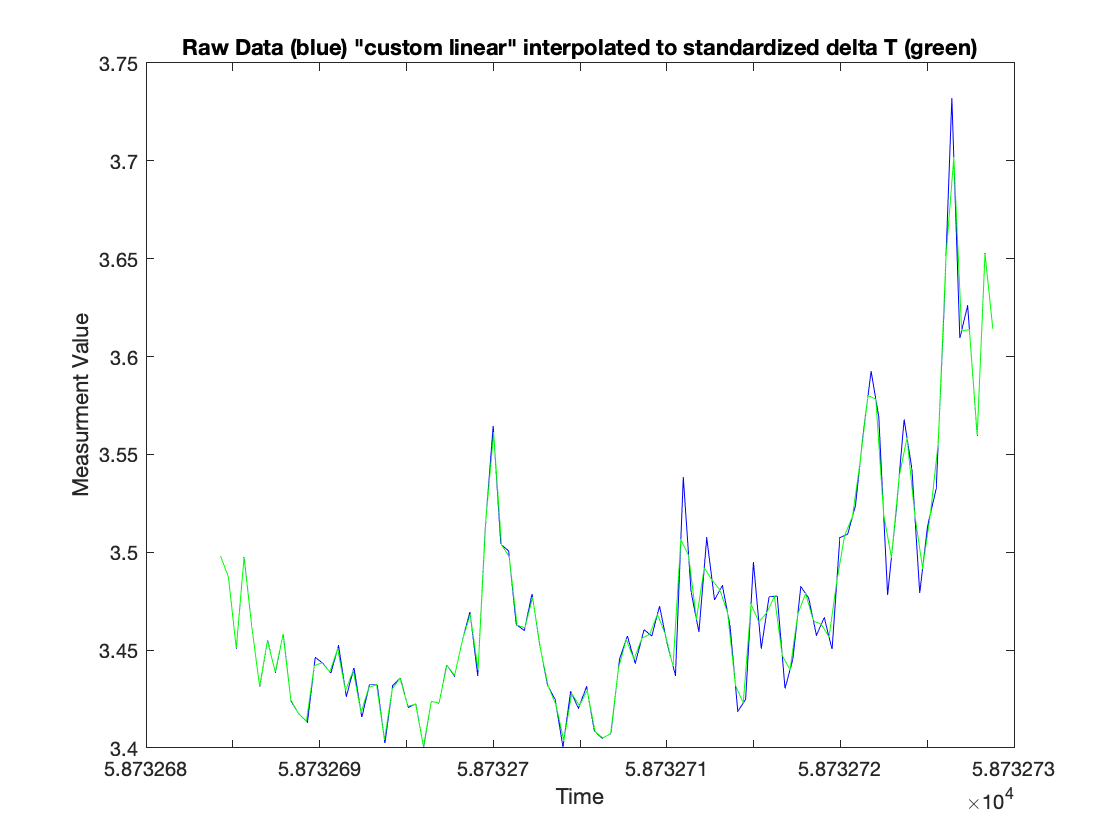

%--Call Joe's Linear Interpolation Function--
[Tnew,Mnew] = Interp_Lin(BD55_441(1:100,1),BD55_441(1:100,2));

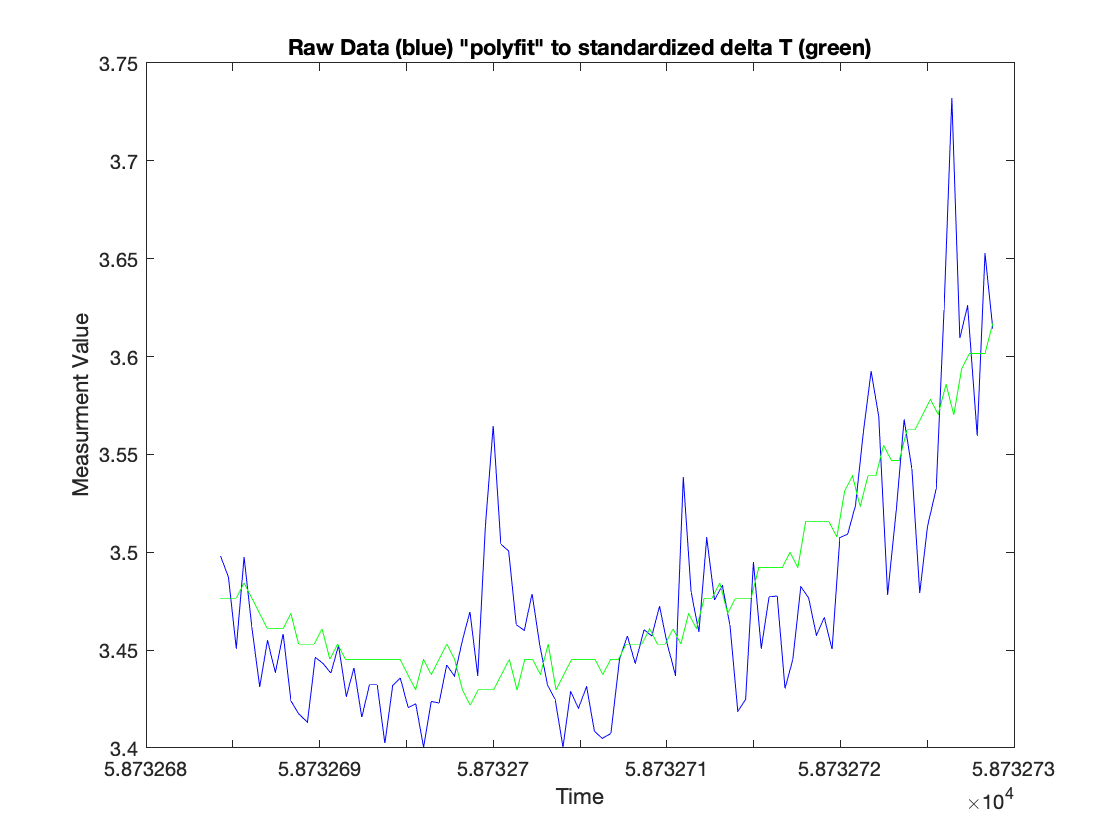


%--Call Matlab's built in Interpolation functions

%[n] = Interp_nearest(BD55_441(1:100,1),BD55_441(1:100,2));
%[n] = Interp_linear(BD55_441(1:100,1),BD55_441(1:100,2));
%[n] = Interp_spline(BD55_441(1:100,1),BD55_441(1:100,2));
[n] = Interp_polyfit(BD55_441(1:100,1),BD55_441(1:100,2));


%--R_Flux-----------------------
%{
plot(BD55_441(:,3),BD55_441(:,4),'*')
title('Flux vs time for BD+55\_441 R filter');
xlabel('time');
ylabel('flux');
%}

disp('R Filter')

R Filter


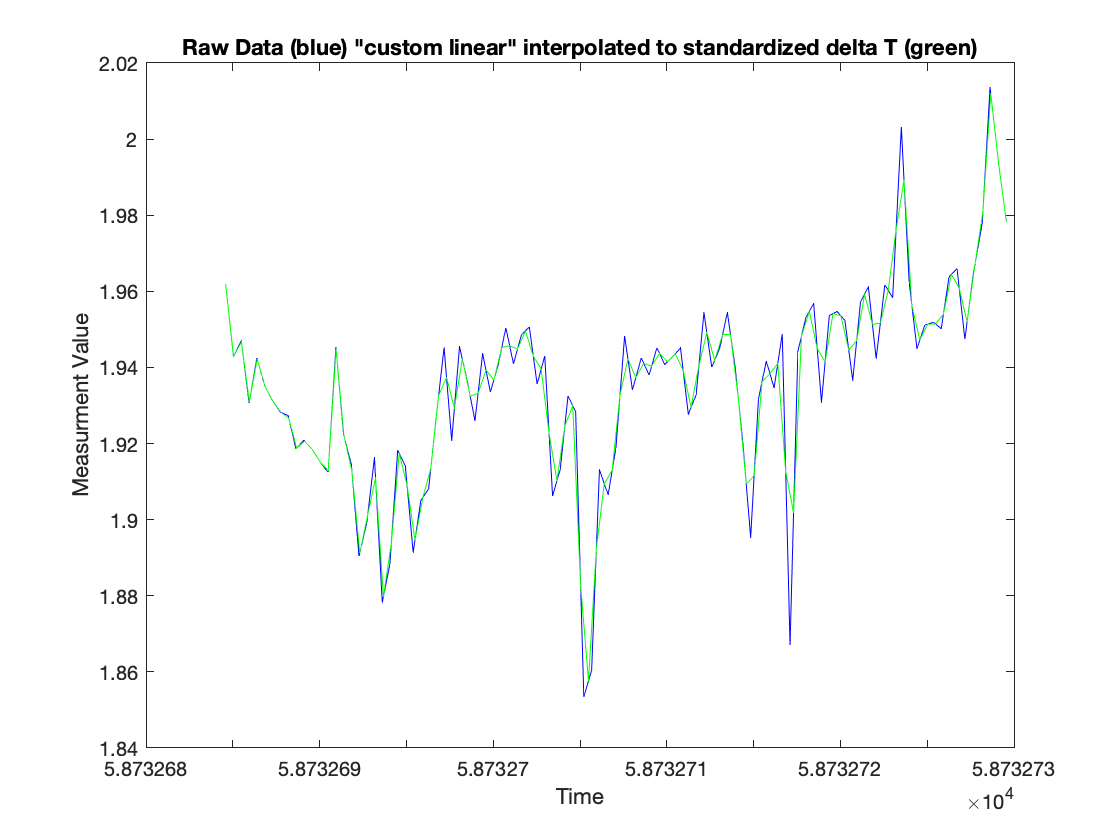

%--Call Joe's Linear Interpolation Function--
[Tnew,Mnew] = Interp_Lin(BD55_441(1:100,3),BD55_441(1:100,4));

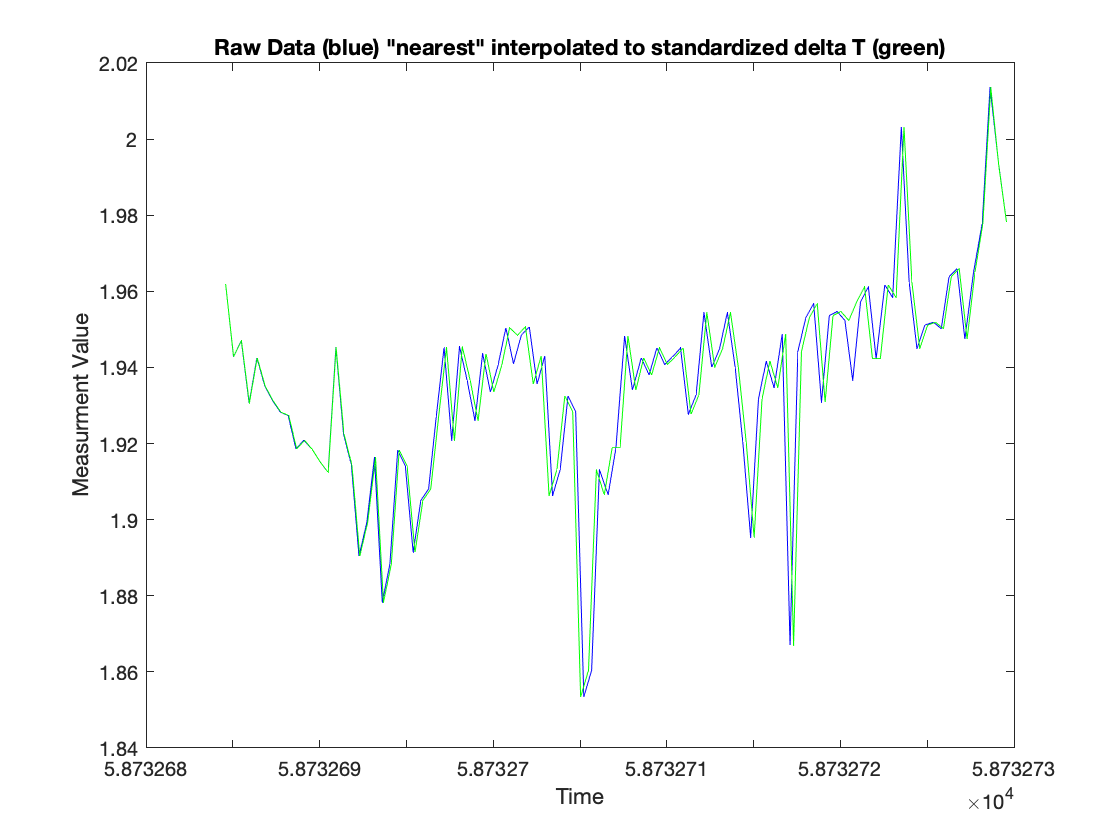


%--Call Matlab's built in Interpolation functions
[n] = Interp_nearest(BD55_441(1:100,3),BD55_441(1:100,4));

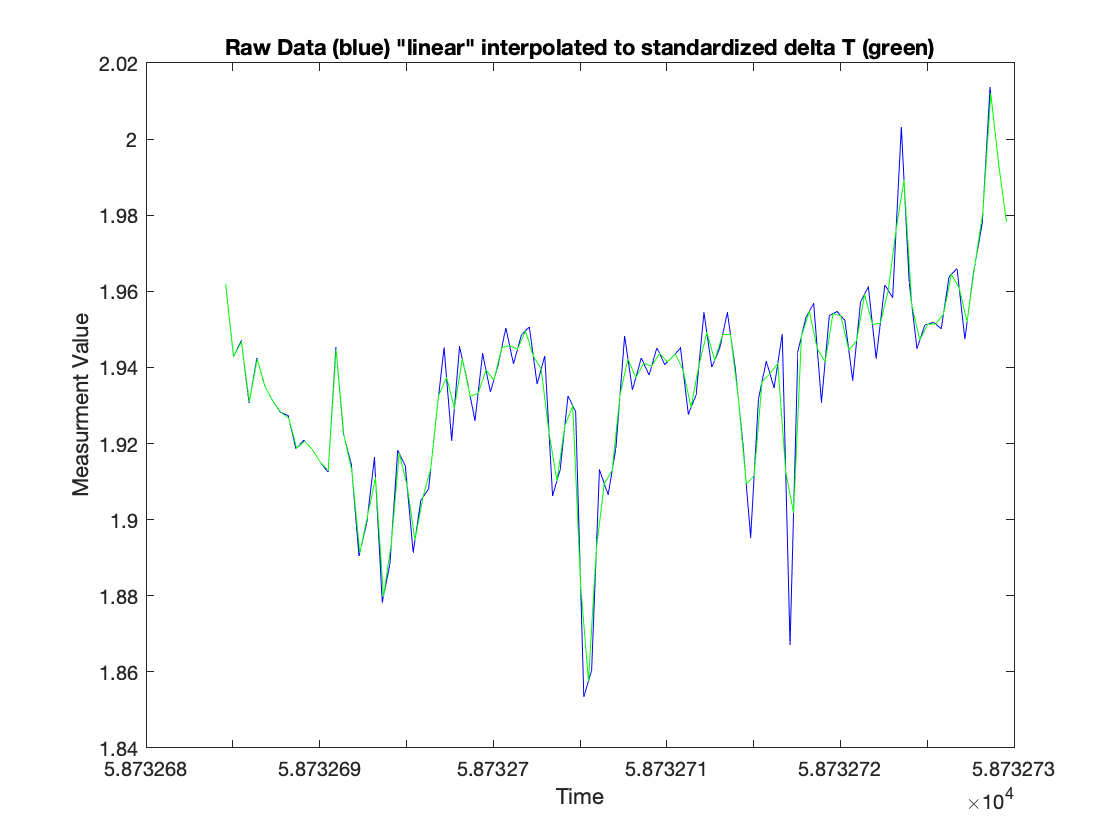

[n] = Interp_linear(BD55_441(1:100,3),BD55_441(1:100,4));

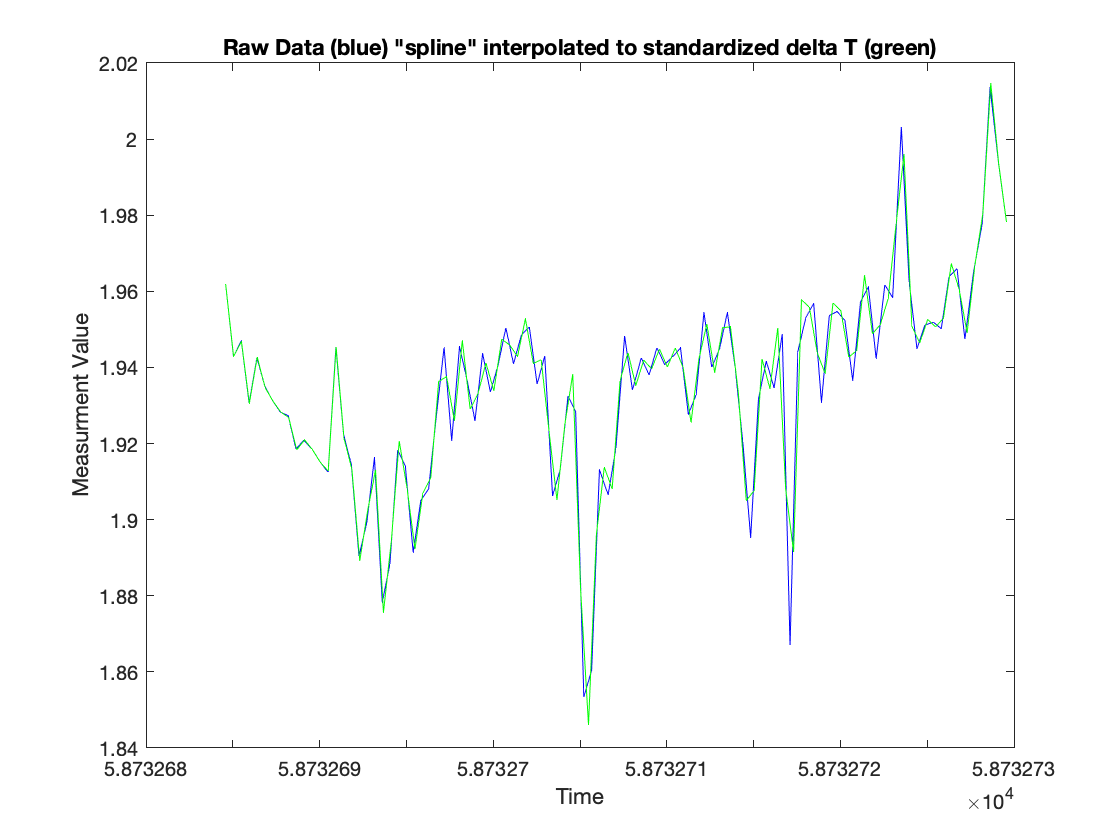

[n] = Interp_spline(BD55_441(1:100,3),BD55_441(1:100,4));

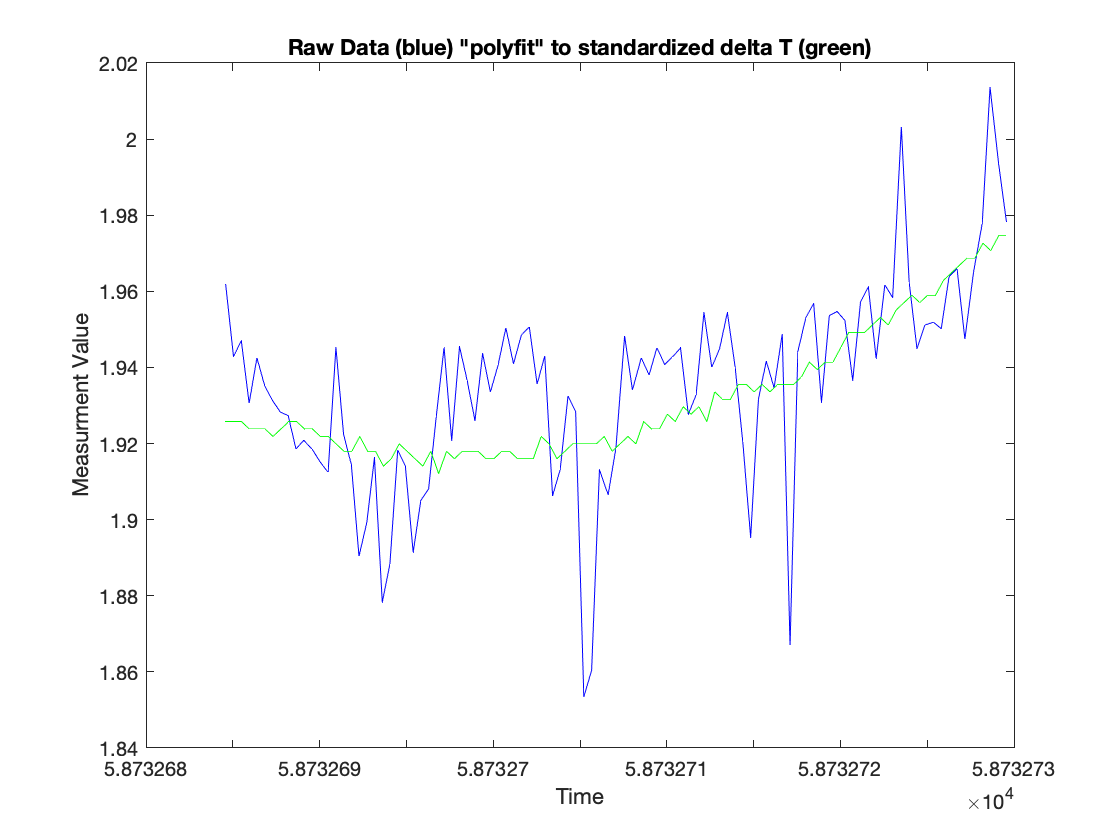

[n] = Interp_polyfit(BD55_441(1:100,3),BD55_441(1:100,4));





%--V_Flux-----------------------
%{
plot(BD55_441(:,5),BD55_441(:,6),'*')
title('Flux vs time for BD+55\_441 V filter');
xlabel('time');
ylabel('flux');
%}
disp('V Filter')

V Filter


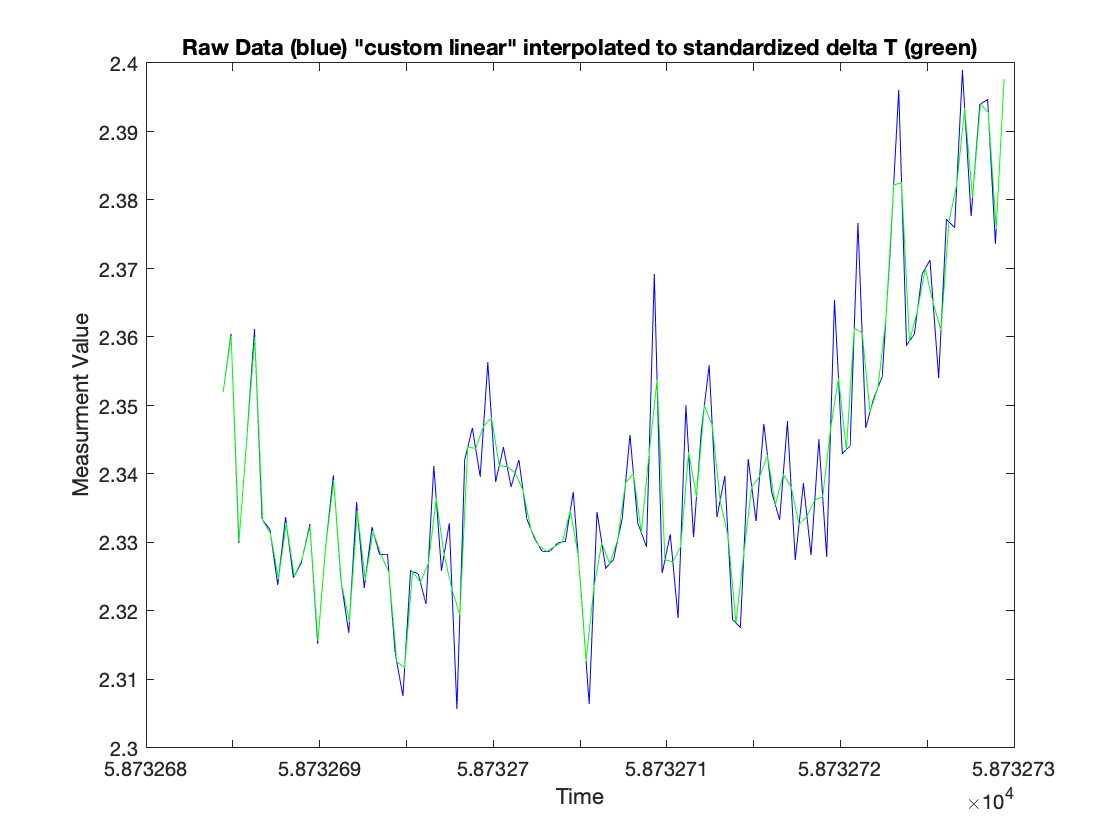

%--Call Joe's Linear Interpolation Function--
[Tnew,Mnew] = Interp_Lin(BD55_441(1:100,5),BD55_441(1:100,6));

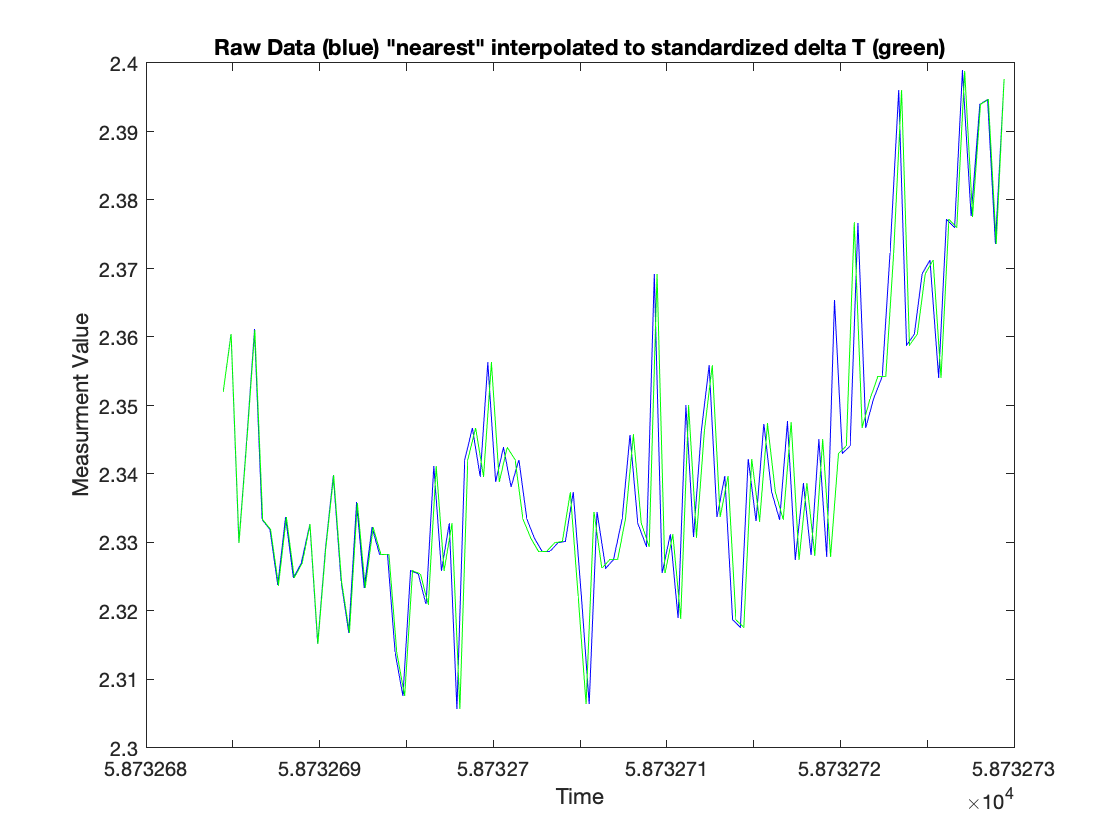


%--Call Matlab's built in Interpolation functions
[n] = Interp_nearest(BD55_441(1:100,5),BD55_441(1:100,6));

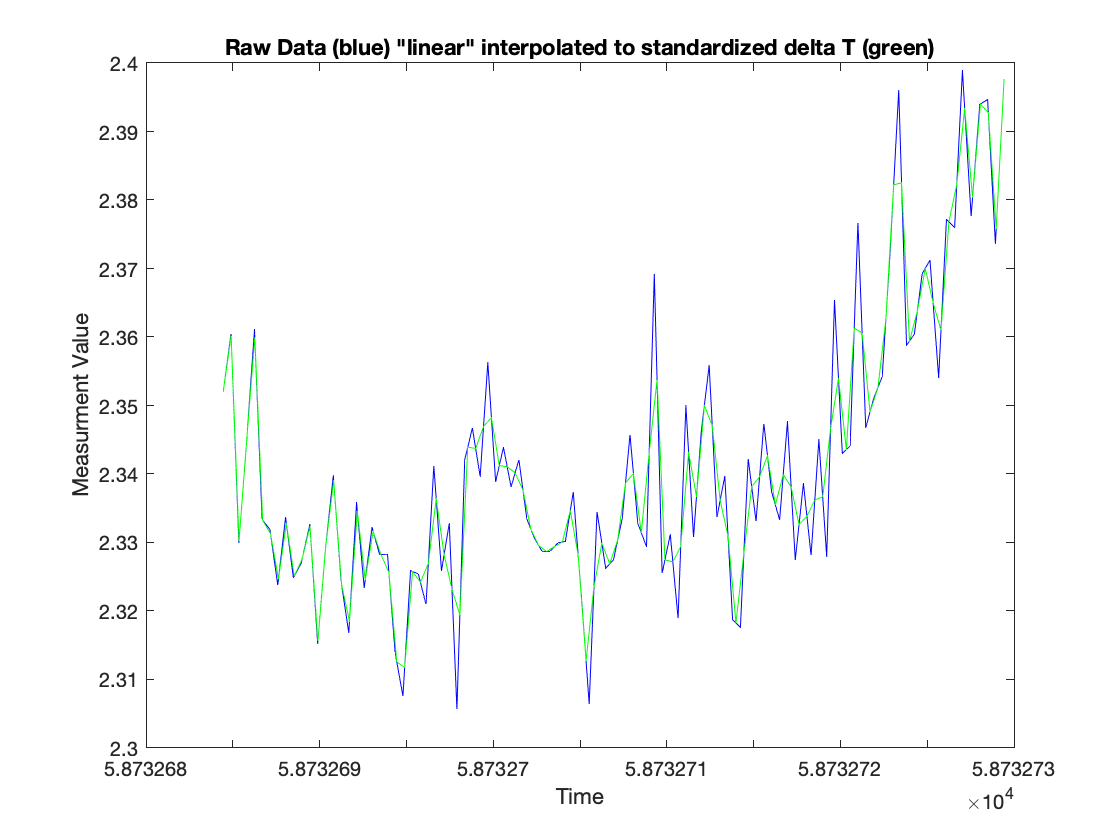

[n] = Interp_linear(BD55_441(1:100,5),BD55_441(1:100,6));

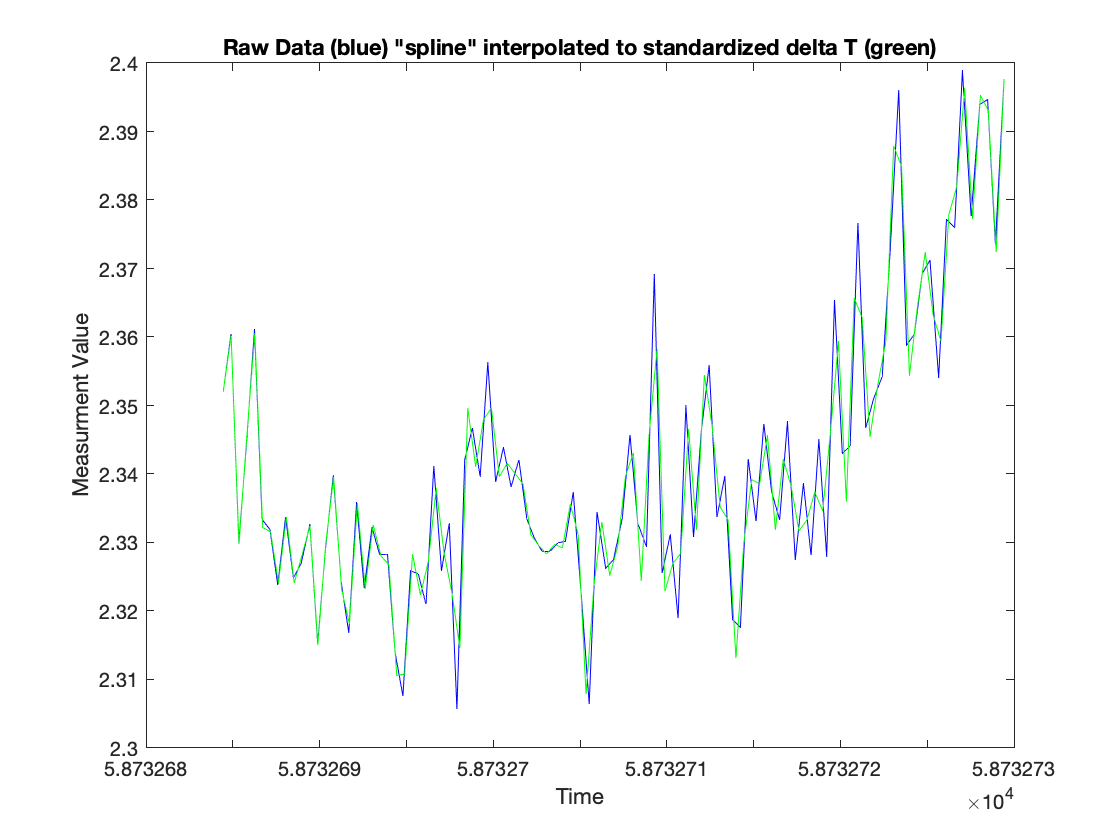

[n] = Interp_spline(BD55_441(1:100,5),BD55_441(1:100,6));

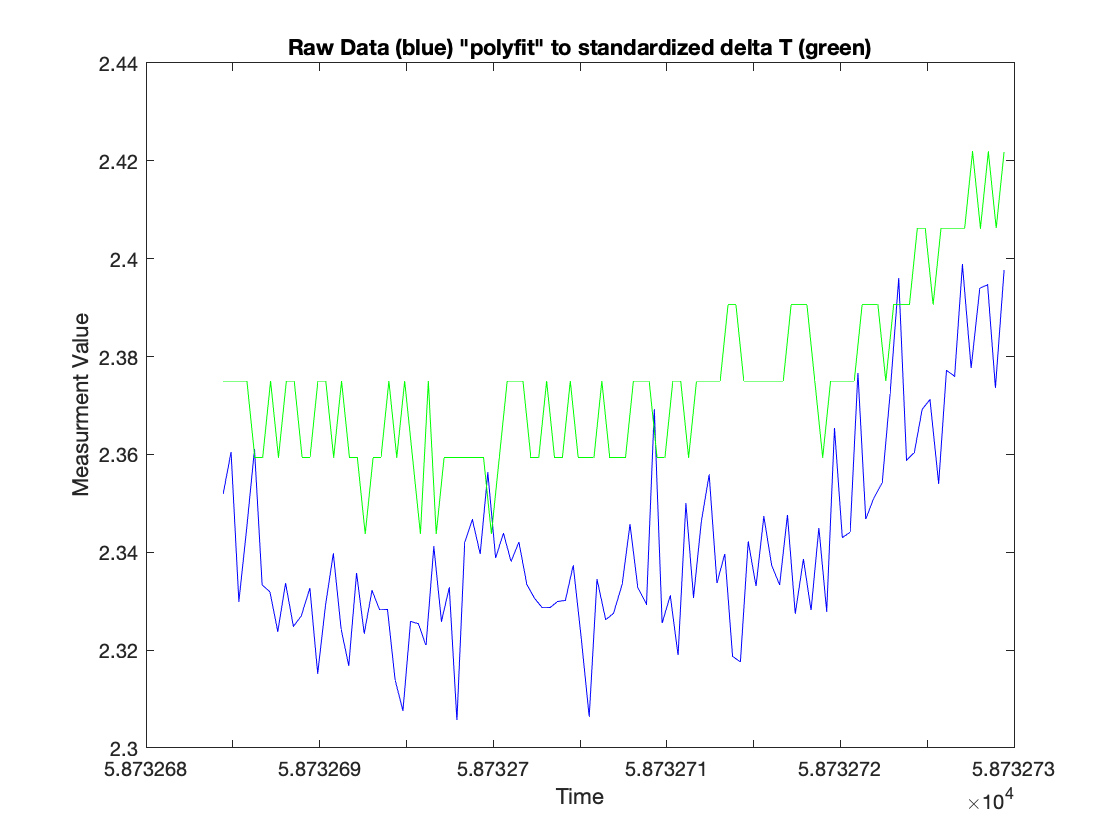

[n] = Interp_polyfit(BD55_441(1:100,5),BD55_441(1:100,6));

## Input all data

**Text files:**

%BD+48_1098
opts = detectImportOptions("BD+48_1098.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
BD48_1098 = readmatrix("BD+55_441.txt",opts); %the matrix data of the text file
%preview("BD+48_1098.txt",opts)
whos BD48_1098

  Name             Size            Bytes  Class     Attributes

  BD48_1098      101x6              4848  double              



%HD28497
opts = detectImportOptions("HD28497.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD28497 = readmatrix("HD28497.txt",opts); %the matrix data of the text file
%preview("HD28497.txt",opts)
whos HD28497

  Name           Size            Bytes  Class     Attributes

  HD28497      600x6             28800  double              



%HD46131
opts = detectImportOptions("HD46131.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD46131 = readmatrix("HD46131.txt",opts); %the matrix data of the text file
%preview("HD46131.txt",opts)
whos HD46131

  Name           Size            Bytes  Class     Attributes

  HD46131      250x6             12000  double              



%HD88661
opts = detectImportOptions("HD88661.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD88661 = readmatrix("HD88661.txt",opts); %the matrix data of the text file
%preview("HD88661.txt",opts)
whos HD88661

  Name          Size            Bytes  Class     Attributes

  HD88661      36x6              1728  double              



%HD105521
opts = detectImportOptions("HD105521.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD105521 = readmatrix("HD105521.txt",opts); %the matrix data of the text file
%preview("HD105521.txt",opts)
whos HD105521

  Name            Size            Bytes  Class     Attributes

  HD105521      180x6              8640  double              



%HD105521
opts = detectImportOptions("HD105521.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD105521 = readmatrix("HD105521.txt",opts); %the matrix data of the text file
%preview("HD105521.txt",opts)
whos HD105521

  Name            Size            Bytes  Class     Attributes

  HD105521      180x6              8640  double              



**CSV files**

%HD106306
%B_filter
opts = detectImportOptions('HD106306_B.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD106306_B.csv",opts)
HD106306_B = readmatrix("HD106306_B.csv",opts);

%R_filter
opts = detectImportOptions('HD106306_R.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD106306_R.csv",opts)
HD106306_R = readmatrix("HD106306_R.csv",opts);

%V_filter
opts = detectImportOptions('HD106306_V.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD106306_V.csv",opts)
HD106306_V = readmatrix("HD106306_V.csv",opts);

HD106306 = [HD106306_B HD106306_R HD106306_V]; %the matrix data of the text file
whos HD106306

  Name            Size            Bytes  Class     Attributes

  HD106306      100x6              4800  double              



%HD147302
%B_filter
opts = detectImportOptions('HD147302_B.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD147302_B.csv",opts)
HD147302_B = readmatrix("HD147302_B.csv",opts);

%R_filter
opts = detectImportOptions('HD147302_R.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD147302_R.csv",opts)
HD147302_R = readmatrix("HD147302_R.csv",opts);

%V_filter
opts = detectImportOptions('HD147302_V.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD147302_V.csv",opts)
HD147302_V = readmatrix("HD147302_V.csv",opts);

HD147302 = [HD147302_B HD147302_R HD147302_V]; %the matrix data of the text file
whos HD147302

  Name            Size            Bytes  Class     Attributes

  HD147302      100x6              4800  double              



HD152060 and HD209522 can't be described in the same form as the others. Will investigate

function [Tnew,Mnew] = Interp_Lin(T,M)
%This is Joe's custom linear interpolation:
% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1
    
    sum = sum + abs(T(l+1) - T(l));
end

% -- find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

%--Calculate Mnew values--
m = numel(Tnew);
Mnew = zeros(1,m);

Mnew(1) = M(1);
Mnew(m) = M(n);

for l = 2:m-1
    for k = 1:n  
       if T(k) <= Tnew(l)
           if Tnew(l) <= T(k+1)
               Mnew(l) =   ( M(k+1) - M(k) ) ./ ( T(k+1) - T(k) ) .* ( Tnew(l)-T(k) ) + M(k) ;  %eq for a line. i.e. y = mx + b
           end
       end
    end
end




plot(T,M,'b',Tnew,Mnew,'g')
title('Raw Data (blue) "custom linear" interpolated to standardized delta T (green)')
xlabel('Time')
ylabel('Measurment Value')
end



%-- Input into various built-in Matlab Functions---------------------


function [n] = Interp_nearest(T,M)

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1

    sum = sum + abs(T(l+1) - T(l));
end

% -- find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);



Mnew = interp1(T,M,Tnew,'nearest');
plot(T,M,'b',Tnew,Mnew,'g')
title('Raw Data (blue) "nearest" interpolated to standardized delta T (green)')
xlabel('Time')
ylabel('Measurment Value')

end

%--------------------

function [n] = Interp_linear(T,M)

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1

    sum = sum + abs(T(l+1) - T(l));
end

% -- find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);


Mnew = interp1(T,M,Tnew,'linear');
plot(T,M,'b',Tnew,Mnew,'g')
title('Raw Data (blue) "linear" interpolated to standardized delta T (green)')
xlabel('Time')
ylabel('Measurment Value')
end

%------------------------

function [n] = Interp_spline(T,M)

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1

    sum = sum + abs(T(l+1) - T(l));
end

% -- find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);


Mnew = interp1(T,M,Tnew,'spline');
plot(T,M,'b',Tnew,Mnew,'g')
title('Raw Data (blue) "spline" interpolated to standardized delta T (green)')
xlabel('Time')
ylabel('Measurment Value')
end

%-------------------------------

function [n] = Interp_polyfit(T,M)

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1

    sum = sum + abs(T(l+1) - T(l));
end

% -- find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

n = numel(T);
p = polyfit(T,M,5);
Mnew = polyval(p,Tnew);
plot(T,M,'b',Tnew,Mnew,'g')
title('Raw Data (blue) "polyfit" to standardized delta T (green)')
xlabel('Time')
ylabel('Measurment Value')

end








